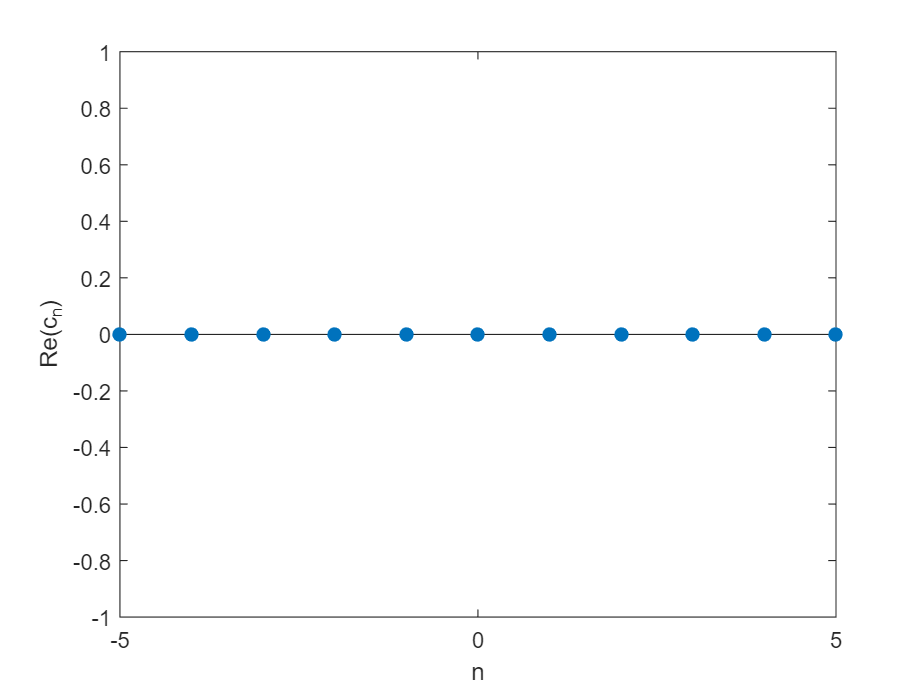

% Coefficients
Nfreq = 5;
n = -Nfreq:Nfreq;
cn = zeros(size(n));
cn(3+Nfreq+1) = -2i;
cn(-3+Nfreq+1) = 2i;

figure
stem(n,real(cn),"filled")
xlabel("n")
ylabel("Re(c_n)")

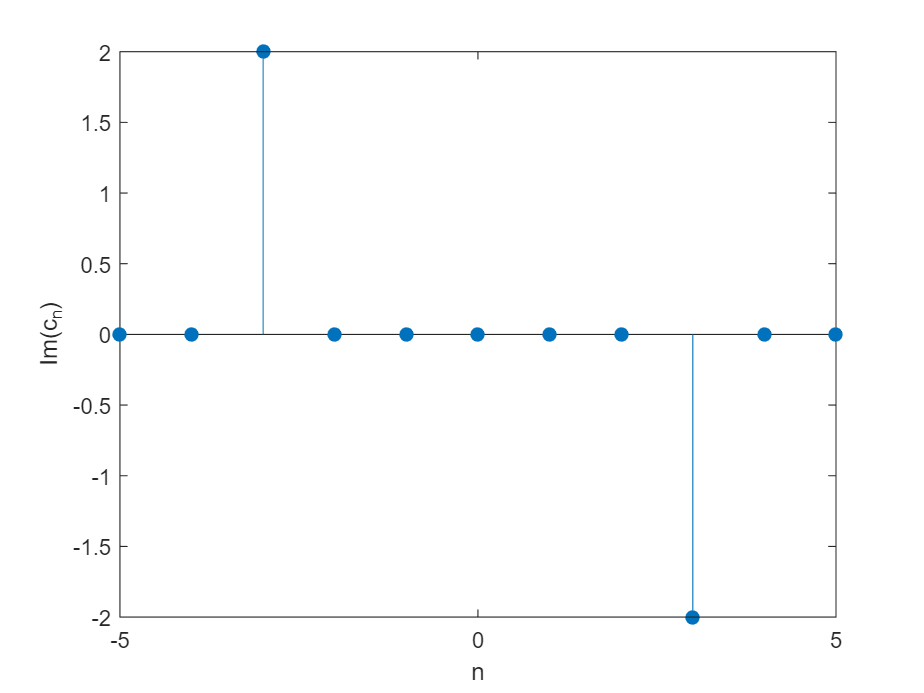


figure
stem(n,imag(cn),"filled")
xlabel("n")
ylabel("Im(c_n)")

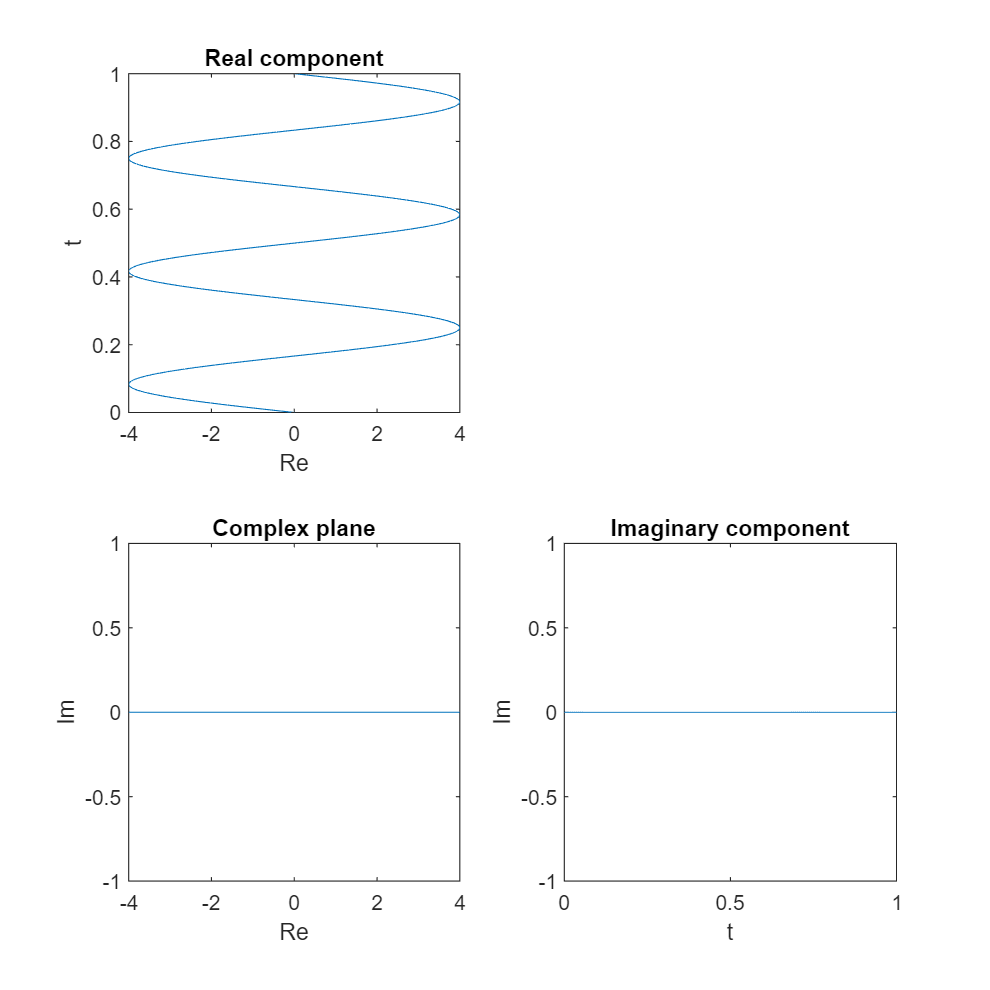


% Phase and magnitude


% Time variable
tf = 1;
t = linspace(0,tf,500);

% The series
L = 0.5;

y = t*0;
for k = 1:numel(n)
    y = y + cn(k)*exp(-1i*n(k)*pi/L*t);
end


figure("position",[1,1,600,600])
subplot(2,2,3)
plot(real(y),imag(y))
title("Complex plane")
xlabel("Re")
ylabel("Im")

subplot(2,2,1)
plot(real(y),t)
xlabel("Re")
ylabel("t")
title("Real component")

subplot(2,2,4)
plot(t,imag(y))
xlabel("t")
ylabel("Im")
title("Imaginary component")